# Examples 2.12-2.13: Quantiles and Confidence Region for Mixing Problem

Note: this script reproduces Examples 2.12 and 2.13 (Section 2.2.2) of **Statistics for Chemical Engineers**: the output flow F3 ~ N(30,1) of a mixer. Victor Z UW-Madison, 2020 compare cdfs for standard normal and normal for mixing problem

clc; clear all; close all hidden;

x=linspace(-4,4);
n=length(x);
mu=30; sig=1;

## Example 2.12: quantiles

prob level

alpha=0.977

alpha = 0.9770


% the quantile for N(0,1) - zalpha
q1 = norminv(alpha,0,1)

q1 = 1.9954


% the quantile of N(mu,sigma) - Qalpha
q1p = mu+q1*sig

q1p = 31.9954


% confirm this is true
q1p = norminv(alpha,mu,sig)

q1p = 31.9954

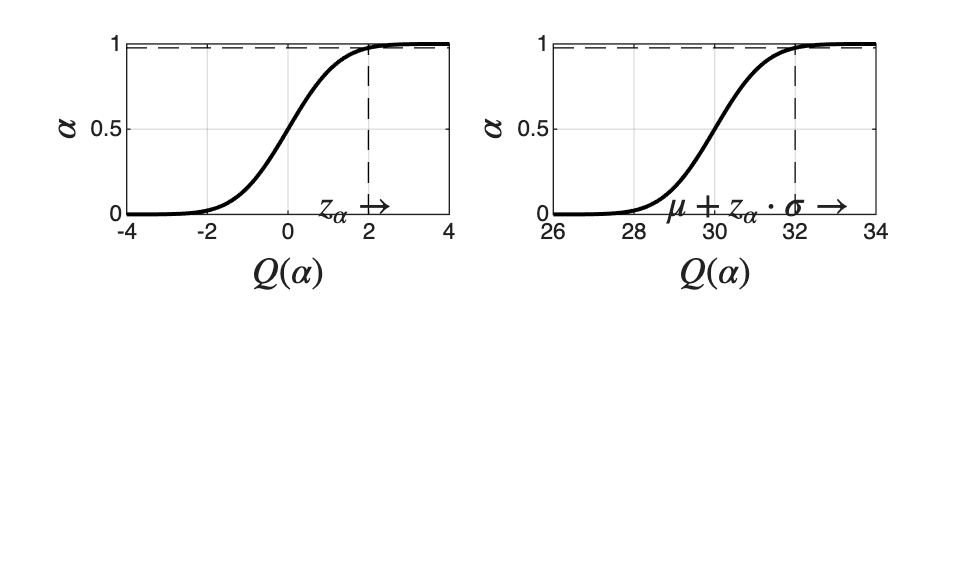


% plot quantile function for N(0,1)
subplot(2,2,1)
plot(x,normcdf(x,0,1),'black','LineWidth',1.5)
grid on
hold on
plot(x,alpha*ones(length(x),1),'black--')
hold on
plot(q1*ones(n,1),linspace(0,1),'black--')
text(0.68,0.05,'$z_\alpha\rightarrow$','Interpreter','latex','FontSize',14)
xlabel('$Q(\alpha)$','Interpreter','latex','FontSize',14)
ylabel('$\alpha$','Interpreter','latex','FontSize',14)

% plot quantile function for N(mu,sigma)
x=linspace(mu-4*sig,mu+4*sig);
subplot(2,2,2)
plot(x,normcdf(x,mu,sig),'black','LineWidth',1.5)
grid on
hold on
plot(x,alpha*ones(length(x),1),'black--')
hold on
plot(q1p*ones(n,1),linspace(0,1),'black--')
text(28.7,0.05,'$\mu+z_\alpha\cdot \sigma\rightarrow$','Interpreter','latex','FontSize',14)
xlabel('$Q(\alpha)$','Interpreter','latex','FontSize',14)
ylabel('$\alpha$','Interpreter','latex','FontSize',14)

print -depsc ch2_mixing_gauss.eps

## Example 2.13: 90% confidence region

compute 90% confidence interval

figure(3)
mu=30; sig=1;
x=linspace(mu-4*sig,mu+4*sig);
n=length(x);

% prob level
alpha=0.10

alpha = 0.1000


% the quantile for N(0,1) - zalpha
q = norminv(1-alpha/2,0,1)

q = 1.6449


% intervals
 qup = mu+q*sig

qup = 31.6449

qlow = mu-q*sig

qlow = 28.3551

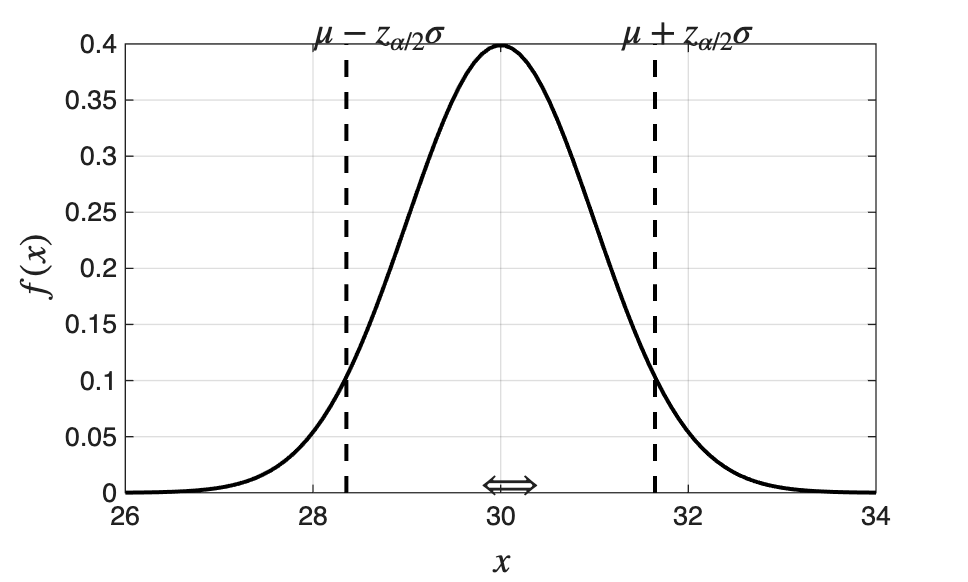


plot(x,normpdf(x,mu,sig),'black','LineWidth',1.5)
grid on
hold on
plot(qup*ones(n,1),linspace(0,0.4),'black--','LineWidth',1.5)
plot(qlow*ones(n,1),linspace(0,0.4),'black--','LineWidth',1.5)
text(29.75,0.01,'$\Longleftrightarrow$','Interpreter','latex','FontSize',14)
text(qup-0.4,0.41,'$\mu+ z_{\alpha/2}\sigma$','Interpreter','latex','FontSize',14)
text(qlow-0.4,0.41,'$\mu- z_{\alpha/2}\sigma$','Interpreter','latex','FontSize',14)
xlabel('$x$','Interpreter','latex','FontSize',14)
ylabel('$f(x)$','Interpreter','latex','FontSize',14)

print -depsc ch2_conf_mixing.eps

## Note

As in the book, we are 97.7% confident that F3 is below 32 gpm, and F3 lies in [28.36, 31.64] gpm with 90% probability.